% main_simulation.m
% 振动主动控制仿真主程序
% 支持三种模式：
%   MODE = 1 : 纯 FxLMS（用于收集训练数据）
%   MODE = 2 : 混合控制（加载预训练神经网络，固定 α=1）
%   MODE = 3 : 自适应混合控制（状态机自动调整 α，可选）

clear; clc; close all;

%% ==================== 用户配置 ====================
MODE = 2;   % 1:纯FxLMS(收集数据)  2:混合控制(固定α=1)  3:自适应混合控制

% 仿真参数
fs = 10000;                 % 采样率 [Hz]
dt = 1/fs;                  % 时间步长 [s]
duration = 10;              % 仿真时长 [s]
n_samples = duration * fs;
t = (0:n_samples-1)' / fs;

% 振动工况
vib_freq = 100;             % 振动频率 [Hz]
vib_amp = 5.0;              % 振动幅值 [m/s²]

% 控制器参数
L = 128;                    % FxLMS 滤波器阶数
mu_fixed = 5e-6;            % 固定步长
delta = 1e-6;               % 正则化参数（未使用归一化）

% 次级路径参数
delay = 4;                  % 延迟步数
s_hat_gain = -0.2;          % 次级路径增益（负号由脉冲测试确定）

% 神经网络参数
input_dim = 19;
hidden_dims = [128, 64];

% 数据收集（仅 MODE=1 时有效）
collect_interval = 10;      % 每10步记录一个样本

% 混合控制参数（MODE=2 或 3 时有效）
alpha_fixed = 1;            % MODE=2 时使用的固定混合系数
alpha_min = 0;
alpha_max = 0.15;             % MODE=3 时最大混合系数
performance_window = 100;    % 性能评估窗口

%% ==================== 初始化物理模型 ====================
vib_source = VibrationSource();
vib_source.frequencies = vib_freq;
vib_source.amplitudes = vib_amp;
vib_source.phases = 0;
vib_source.noise_level = 0.05;

structure = StructuralDynamics(fs, 5, false);

负载 5.0 N: 目标平均阻尼比 = 0.0250
  各模态阻尼比: [0.0150, 0.0225, 0.0375]



actuator = PiezoActuator();

作动器状态已重置


actuator.K = 0.85;
actuator.fn = 3100;
actuator.zeta = 0.023;
actuator.alpha = 0.15;
actuator.beta = 0.035;
actuator.gamma = 0.025;

sensor = Accelerometer(fs);

加速度计初始化: PCB 352C33
  灵敏度: 98 mV/g
  带宽: 0.5-3000 Hz
  噪声密度: 6.0 μg/√Hz


sensor.sensitivity = 98;
sensor.bandwidth = [0.5, 3000];
sensor.noise_density = 6e-6;

%% ==================== 次级路径 ====================
fprintf('次级路径: 延迟 %d 步, 增益 %.2f\n', delay, s_hat_gain);

次级路径: 延迟 4 步, 增益 -0.20


s_hat = zeros(delay+1, 1);
s_hat(end) = s_hat_gain;

%% ==================== 控制器初始化 ====================
% FxLMS 结构
fxLMS = struct();
fxLMS.order = L;
fxLMS.w = zeros(L,1);
fxLMS.S_hat = s_hat(:);
buffer_len = max(L, length(s_hat));
fxLMS.x_buffer = zeros(buffer_len,1);
fxLMS.xf_buffer = zeros(L,1);

% 神经网络（仅在混合模式时加载）
if MODE == 2 || MODE == 3
    S = load('trained_nn.mat');
    if isfield(S, 'nn') && isa(S.nn, 'ResidualNN_Simple')
        nn = S.nn;
        fprintf('已加载预训练神经网络，类型：%s\n', class(nn));
    else
        error('trained_nn.mat 中未找到有效的 ResidualNN_Simple 对象');
    end
else
    nn = [];
end

已加载预训练神经网络，类型：ResidualNN_Simple




% 混合控制器（仅在自适应模式时创建）
if MODE == 3
    hybrid = HybridController(alpha_min, alpha_max, performance_window);
    hybrid.verbose = true;
else
    hybrid = [];
end

%% ==================== 预分配数组 ====================
vibration_raw = zeros(n_samples,1);
control_signal = zeros(n_samples,1);
error_signal = zeros(n_samples,1);
y_linear = zeros(n_samples,1);
y_nn = zeros(n_samples,1);
alpha_history = zeros(n_samples,1);
mu_history = zeros(n_samples,1);
rms_history = zeros(n_samples,1);

% 数据收集（仅 MODE=1 时使用）
if MODE == 1
    data_collect = struct();
    data_collect.features = [];
    data_collect.targets = [];
end

%% ==================== 主仿真循环 ====================
acc_control = 0;   % 上一时刻控制产生的加速度
fprintf('开始仿真 (模式 %d)...\n', MODE);

开始仿真 (模式 2)...


tic;

for k = 1:n_samples
    % ---- 生成原始振动 ----
    condition = struct('spindle_rpm', 3000, 'enable_noise', true, ...
        'enable_frequency_modulation', false, ...
        'enable_amplitude_modulation', false, ...
        'enable_random_shock', false);
    vibration_raw(k) = generate_vibration(vib_source, t(k), condition);
    
    % ---- 当前误差（原始振动 + 上一时刻控制效果） ----
    error_signal(k) = vibration_raw(k) + acc_control;
    
    % ---- 提取特征（用于神经网络） ----
    if k >= input_dim
        features = extract_features(vibration_raw, error_signal, control_signal, k, input_dim);
    else
        features = zeros(1, input_dim);
    end
    
    % ---- FxLMS 更新 ----
    if k >= L
        % 更新参考信号缓冲区
        fxLMS.x_buffer = [vibration_raw(k); fxLMS.x_buffer(1:end-1)];
        % 计算滤波参考信号
        xf = 0;
        M = length(fxLMS.S_hat);
        for j = 1:min(M, k)
            xf = xf + fxLMS.S_hat(j) * fxLMS.x_buffer(j);
        end
        fxLMS.xf_buffer = [xf; fxLMS.xf_buffer(1:end-1)];
        % 控制输出
        y_linear(k) = fxLMS.w' * fxLMS.x_buffer(1:L);
        % 系数更新
        fxLMS.w = fxLMS.w - mu_fixed * error_signal(k) * fxLMS.xf_buffer;
    else
        y_linear(k) = 0;
    end
    
    % ---- 网络信息测试 ----
    if MODE~=1
       if k == input_dim
            % 打印标准化参数
            fprintf('feature_mean 前5个: '); fprintf('%.3f ', nn.feature_mean(1:5)); fprintf('\n');
            fprintf('feature_std  前5个: '); fprintf('%.3f ', nn.feature_std(1:5)); fprintf('\n');
            % 打印当前特征
            fprintf('features 前5个: '); fprintf('%.3f ', features(1:5)); fprintf('\n');
            % 手动计算标准化后的值
            x_norm = (features' - nn.feature_mean) ./ nn.feature_std;
            fprintf('x_norm 前5个: '); fprintf('%.3f ', x_norm(1:5)); fprintf('\n');
            % 计算网络第一层输出
            h1 = max(0, nn.W1 * x_norm + nn.b1);
            fprintf('h1 范围: [%.2f, %.2f]\n', min(h1), max(h1));
       end 
    end
    


    % ---- 神经网络补偿（仅在混合模式且 k>=input_dim 时） ----
    if (MODE == 2 || MODE == 3) && k >= input_dim
        y_nn(k) = nn.forward(features');
    else
        y_nn(k) = 0;
    end
    
    % ---- 混合控制输出 ----
    switch MODE
        case 1   % 纯 FxLMS
            y_total = y_linear(k);
            
        case 2   % 混合控制固定 α=1  可调整缩放因子0.1-0.05
            %y_total = y_linear(k) + 0.1*y_nn(k);
            scale = 1/5;   % 与数据收集时相同的缩放因子
            y_total = y_linear(k) + scale * y_nn(k);
            
        case 3   % 自适应混合控制
            alpha = hybrid.alpha;   % 当前混合系数
            y_total = y_linear(k) + alpha * y_nn(k);
            alpha_history(k) = alpha;
    end
    % 限幅
    y_total = max(min(y_total, 10), -10);
    control_signal(k) = y_total;
    
    % ---- 执行控制，获取结构响应 ----
    [~, actuator_force] = actuator.actuate(control_signal(k), dt);
    [~, ~] = structure.respond(actuator_force, dt);
    acc_control = structure.get_acceleration(2);   % 传感器位置加速度
    
    % ---- 自适应混合系数更新（仅 MODE=3） ----
    if MODE == 3
        hybrid.adapt_alpha(error_signal(k), vibration_raw(k));
    end
    
    % ---- 数据收集（仅 MODE=1） ----
    % 丢前2秒，防止数据过杂
    scale = 5;   % 缩放因子，可根据残差实际范围调整（例如 5）
    if MODE == 1 && k >= input_dim && k > 20000 && mod(k, collect_interval) == 0
        residual = (error_signal(k) - y_linear(k)) / scale;
        data_collect.features(end+1, :) = features;
        data_collect.targets(end+1) = residual;
    end
    
    % ---- 滑动 RMS（用于监控） ----
    window = 100;
    if k >= window
        rms_history(k) = rms(error_signal(k-window+1:k));
    end
    
    % ---- 进度显示 ----
    if mod(k, floor(n_samples/10)) == 0
        if MODE == 3
            fprintf('进度: %.0f%%, RMS误差: %.3f, alpha: %.3f\n', ...
                100*k/n_samples, rms_history(k), hybrid.alpha);
        else
            fprintf('进度: %.0f%%, RMS误差: %.3f\n', 100*k/n_samples, rms_history(k));
        end
    end
    
    % ---- 可选：打印前200步调试信息 ----
    if k <= 200
        if MODE == 1
            fprintf('k=%d, err=%.3f, y_lin=%.3f, norm(w)=%.3e, xf1=%.3f\n', ...
                k, error_signal(k), y_linear(k), norm(fxLMS.w), fxLMS.xf_buffer(1));
        end
        if MODE == 2
            fprintf('k=%d, y_lin=%.3f, y_nn=%.3f, err=%.3f\n', k, y_linear(k), y_nn(k), error_signal(k));
        end
    end

    % ---- 可选：打印网络调试信息 ----
    if MODE~=1
        if k >= 19 && k <= 30
            x = features';  % input_dim x 1
            x_norm = (x - nn.feature_mean) ./ nn.feature_std;
            fprintf('k=%d, x_norm(1:5)=', k); fprintf('%.2f ', x_norm(1:5)); fprintf('\n');
            h1 = max(0, nn.W1 * x_norm + nn.b1);
            fprintf('h1 range: [%.2f, %.2f]\n', min(h1), max(h1));
            h2 = max(0, nn.W2 * h1 + nn.b2);
            fprintf('h2 range: [%.2f, %.2f]\n', min(h2), max(h2));
            z3 = nn.W3 * h2 + nn.b3;
            fprintf('z3 = %.2f\n', z3);
            y_nn_test = tanh(z3);
            fprintf('y_nn from manual: %.4f\n', y_nn_test);
        end
    end
end

k=1, y_lin=0.000, y_nn=0.000, err=-0.013
k=2, y_lin=0.000, y_nn=0.000, err=0.384
k=3, y_lin=0.000, y_nn=0.000, err=0.604
k=4, y_lin=0.000, y_nn=0.000, err=0.867
k=5, y_lin=0.000, y_nn=0.000, err=1.232
k=6, y_lin=0.000, y_nn=0.000, err=1.498
k=7, y_lin=0.000, y_nn=0.000, err=1.873
k=8, y_lin=0.000, y_nn=0.000, err=2.112
k=9, y_lin=0.000, y_nn=0.000, err=2.463
k=10, y_lin=0.000, y_nn=0.000, err=2.794
k=11, y_lin=0.000, y_nn=0.000, err=2.862
k=12, y_lin=0.000, y_nn=0.000, err=3.236
k=13, y_lin=0.000, y_nn=0.000, err=3.495
k=14, y_lin=0.000, y_nn=0.000, err=3.575
k=15, y_lin=0.000, y_nn=0.000, err=3.876
k=16, y_lin=0.000, y_nn=0.000, err=4.066
k=17, y_lin=0.000, y_nn=0.000, err=4.205
k=18, y_lin=0.000, y_nn=0.000, err=4.424


feature_mean 前5个: 0.001 0.000 0.000 0.000 -0.000 


feature_std  前5个: 3.535 3.536 3.536 3.537 3.536 


features 前5个: 3.236 3.495 3.575 3.876 4.066 


x_norm 前5个: 0.915 0.988 1.011 1.096 1.150 


h1 范围: [0.00, 118.01]


k=19, y_lin=0.000, y_nn=-0.733, err=4.517


k=19, x_norm(1:5)=0.92 0.99 1.01 1.10 1.15 


h1 range: [0.00, 118.01]


h2 range: [0.00, 132.39]


z3 = -36.03


y_nn from manual: -1.0000


k=20, y_lin=0.000, y_nn=-0.737, err=4.664


k=20, x_norm(1:5)=0.99 1.01 1.10 1.15 1.19 


h1 range: [0.00, 119.70]


h2 range: [0.00, 135.68]


z3 = -36.95


y_nn from manual: -1.0000


k=21, y_lin=0.000, y_nn=-0.748, err=4.782


k=21, x_norm(1:5)=1.01 1.10 1.15 1.19 1.25 


h1 range: [0.00, 122.35]


h2 range: [0.00, 139.81]


z3 = -37.72


y_nn from manual: -1.0000


k=22, y_lin=0.000, y_nn=-0.748, err=4.912


k=22, x_norm(1:5)=1.10 1.15 1.19 1.25 1.28 


h1 range: [0.00, 123.93]


h2 range: [0.00, 142.59]


z3 = -38.27


y_nn from manual: -1.0000


k=23, y_lin=0.000, y_nn=-0.748, err=4.948


k=23, x_norm(1:5)=1.15 1.19 1.25 1.28 1.32 


h1 range: [0.00, 126.15]


h2 range: [0.00, 145.72]


z3 = -38.73


y_nn from manual: -1.0000


k=24, y_lin=0.000, y_nn=-0.748, err=5.056


k=24, x_norm(1:5)=1.19 1.25 1.28 1.32 1.34 


h1 range: [0.00, 127.06]


h2 range: [0.00, 147.62]


z3 = -39.52


y_nn from manual: -1.0000


k=25, y_lin=0.000, y_nn=-0.748, err=5.111


k=25, x_norm(1:5)=1.25 1.28 1.32 1.34 1.37 


h1 range: [0.00, 128.87]


h2 range: [0.00, 150.03]


z3 = -39.90


y_nn from manual: -1.0000


k=26, y_lin=0.000, y_nn=-0.748, err=5.152


k=26, x_norm(1:5)=1.28 1.32 1.34 1.37 1.38 


h1 range: [0.00, 129.62]


h2 range: [0.00, 151.43]


z3 = -40.13


y_nn from manual: -1.0000


k=27, y_lin=0.000, y_nn=-0.748, err=5.219


k=27, x_norm(1:5)=1.32 1.34 1.37 1.38 1.40 


h1 range: [0.00, 130.58]


h2 range: [0.00, 152.99]


z3 = -40.67


y_nn from manual: -1.0000


k=28, y_lin=0.000, y_nn=-0.748, err=5.105


k=28, x_norm(1:5)=1.34 1.37 1.38 1.40 1.41 


h1 range: [0.00, 131.86]


h2 range: [0.00, 154.21]


z3 = -40.46


y_nn from manual: -1.0000


k=29, y_lin=0.000, y_nn=-0.748, err=5.126


k=29, x_norm(1:5)=1.37 1.38 1.40 1.41 1.41 


h1 range: [0.00, 130.90]


h2 range: [0.00, 153.45]


z3 = -41.03


y_nn from manual: -1.0000


k=30, y_lin=0.000, y_nn=-0.748, err=5.049


k=30, x_norm(1:5)=1.38 1.40 1.41 1.41 1.43 


h1 range: [0.00, 131.64]


h2 range: [0.00, 153.59]


z3 = -40.88


y_nn from manual: -1.0000


k=31, y_lin=0.000, y_nn=-0.748, err=4.965
k=32, y_lin=0.000, y_nn=-0.748, err=4.847
k=33, y_lin=0.000, y_nn=-0.748, err=4.736
k=34, y_lin=0.000, y_nn=-0.748, err=4.638
k=35, y_lin=0.000, y_nn=-0.748, err=4.577
k=36, y_lin=0.000, y_nn=-0.748, err=4.348
k=37, y_lin=0.000, y_nn=-0.748, err=4.070
k=38, y_lin=0.000, y_nn=-0.733, err=4.036
k=39, y_lin=0.000, y_nn=-0.779, err=3.606
k=40, y_lin=0.000, y_nn=-0.823, err=3.414
k=41, y_lin=0.000, y_nn=-0.845, err=3.233
k=42, y_lin=0.000, y_nn=-0.825, err=2.897
k=43, y_lin=0.000, y_nn=-0.562, err=2.664
k=44, y_lin=0.000, y_nn=-0.335, err=2.316
k=45, y_lin=0.000, y_nn=-0.435, err=2.038
k=46, y_lin=0.000, y_nn=-0.503, err=1.708
k=47, y_lin=0.000, y_nn=-0.468, err=1.461
k=48, y_lin=0.000, y_nn=-0.539, err=1.081
k=49, y_lin=0.000, y_nn=-0.342, err=0.765
k=50, y_lin=0.000, y_nn=-0.071, err=0.459
k=51, y_lin=0.000, y_nn=-0.205, err=0.200
k=52, y_lin=0.000, y_nn=-0.264, err=-0.182
k=53, y_lin=0.000, y_nn=-0.728, err=-0.501
k=54, y_lin=0.000, y_nn=-0.859, 

进度: 10%, RMS误差: 0.467
进度: 20%, RMS误差: 0.433
进度: 30%, RMS误差: 0.437
进度: 40%, RMS误差: 0.393
进度: 50%, RMS误差: 0.484
进度: 60%, RMS误差: 0.476
进度: 70%, RMS误差: 0.503
进度: 80%, RMS误差: 0.516
进度: 90%, RMS误差: 0.498
进度: 100%, RMS误差: 0.531



sim_time = toc;
fprintf('仿真完成，耗时 %.2f 秒\n', sim_time);

仿真完成，耗时 14.65 秒



%% ==================== 性能评估 ====================
fprintf('\n=== 性能评估 ===\n');


=== 性能评估 ===


rms_error = rms(error_signal);
peak_error = max(abs(error_signal));
convergence_idx = find(abs(error_signal) < 0.1 * rms_error, 1);
if ~isempty(convergence_idx)
    convergence_time = convergence_idx / fs;
else
    convergence_time = NaN;
end
fprintf('RMS误差: %.4f m/s²\n', rms_error);

RMS误差: 0.5176 m/s²


fprintf('峰值误差: %.4f m/s²\n', peak_error);

峰值误差: 5.4291 m/s²


fprintf('收敛时间: %.2f s\n', convergence_time);

收敛时间: 0.00 s



% 频域指标
[Pv, f] = pwelch(vibration_raw, hamming(512), 256, 512, fs);
[Pe, ~] = pwelch(error_signal, hamming(512), 256, 512, fs);
total_reduction = 10*log10(sum(Pv)/sum(Pe));
fprintf('总振动抑制比: %.1f dB\n', total_reduction);

总振动抑制比: 17.0 dB


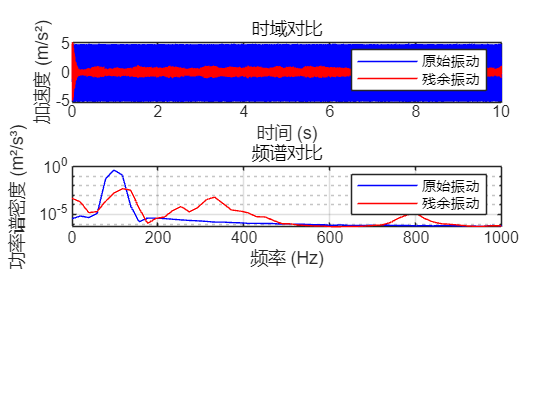


%% ==================== 绘图 ====================
figure;
subplot(3,1,1);
plot(t, vibration_raw, 'b', t, error_signal, 'r');
xlabel('时间 (s)'); ylabel('加速度 (m/s²)');
legend('原始振动', '残余振动'); title('时域对比'); grid on;

subplot(3,1,2);
semilogy(f, Pv, 'b', f, Pe, 'r');
xlabel('频率 (Hz)'); ylabel('功率谱密度 (m²/s³)');
legend('原始振动', '残余振动'); title('频谱对比'); xlim([0,1000]); grid on;

subplot(3,1,3);
if MODE == 3
    plot(t, alpha_history, 'k');
    xlabel('时间 (s)'); ylabel('混合系数 α'); title('混合系数变化'); grid on;
else
    axis off;
end

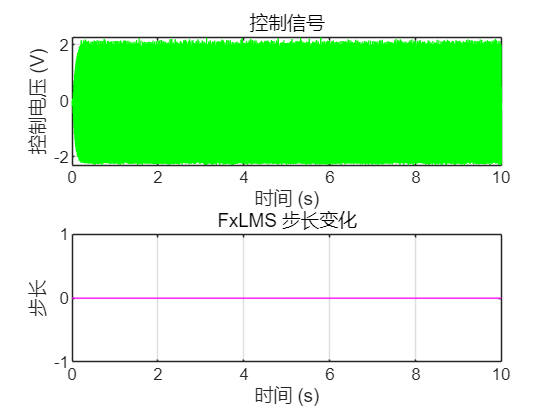


figure;
subplot(2,1,1);
plot(t, control_signal, 'g');
xlabel('时间 (s)'); ylabel('控制电压 (V)'); title('控制信号'); grid on;
subplot(2,1,2);
plot(t, mu_history, 'm');
xlabel('时间 (s)'); ylabel('步长'); title('FxLMS 步长变化'); grid on;


%% ==================== 保存结果 ====================
save('simulation_results.mat', 't', 'vibration_raw', 'error_signal', ...
     'control_signal', 'alpha_history', 'rms_history', ...
     'rms_error', 'peak_error', 'convergence_time', 'total_reduction');

if MODE == 1
    save('training_data.mat', 'data_collect');
    fprintf('训练数据已保存至 training_data.mat，共 %d 个样本\n', size(data_collect.features,1));
end